clear variables; close all; clc;

## DKE Introduction to Bioinformatics 2021

# Sequence alignment 

RING1 (Really Interesting New Gene 1 - yes it really is called that!) is a protein which is involved in lots of complexes (where proteins join together to perform a function) and is involved in regulating the expression of genes.  The strongest known disease association is with asthma, where 9 different studies have associated 7 different positions in the gene with increased chance of asthma when these positions are mutated.  We are going to compare the sequence of this protein in both humans and bearded dragons.

- As we want the peptide sequence and not the nucleotide sequence we use the command **getgenpept** to load data from the online database genbank using the accession code. Load the peptide sequences from both species. (Human RING1 accession number CAA78389; Bearded Dragon RING1 accession number; XP_020670786).

human = getgenpept('CAA78389', SequenceOnly=true);
seqdisp(human)

ans = 7×70 char array
    '  1  MDGTEIAVSP RSLHSELMCP ICLDMLKNTM TTKECLHRFC SDCIVTALRS GNKECPTCRK'
    ' 61  KLVSKRSLRP DPNFDALISK IYPSREEYEA HQDRVLIRLS RLHNQQALSS SIEEGLRMQA'
    '121  MHRAQRVRRP IPGSDQTTTM SGGEGEPGEG EGDGEDVSSD SAPDSAPGPA PKRPRGGGAG'
    '181  GSSVGTGGGG TGGVGGGAGS EDSGDRGGTL GGGTLGPPSP PGAPSPPEPG GEIELVFRPH'
    '241  PLLVEKGEYC QTRYVKTTGN ATVDHLSKYL ALRIALERRQ QQEAGEPGGP GGGASDTGGP'
    '301  DGCGGEGGGA GGGDGPEEPA LPSLEGVSEK QYTIYIAPGG GAFTTLNGSL TLELVNEKFW'
    '361  KVSRPLELCY APTKDPK                                               '


human_length = length(human);
bearded = getgenpept('XP_020670786', SequenceOnly=true);
seqdisp(bearded)

ans = 6×70 char array
    '  1  PCQEAMMDGT EIAVSPRSLH SELMCPICLD MLKHTMTTKE CLHRFCSDCI VTALRSGNKE'
    ' 61  CPTCRKKLVS KRSLRPDPNF DALISKIYPS RDEYEAHQDR VLAKLNRLHN QQALRSSMEE'
    '121  GLKMQAMNRG QRVRKHPQES DNTTFSGAED NCDSRSHLSN ASAPSQPEAG PSRKRSRASD'
    '181  ESCPEPETSH EGGRGSPEPG AEPSSSEIEL VFRPHPVLVD KGAYSQTRYV KTTANATVDH'
    '241  LSKYLALRIA LEEAPGPGPE APALEDVSEK QYTIYITTAG GAFTTLNGSV TLELVNEKYW'
    '301  KLSKPLELYY APTKEQK                                               '


bearded_length = length(bearded);

        2. Use the **seqdotplot** command on these two sequences, label the plot and explain what it shows.

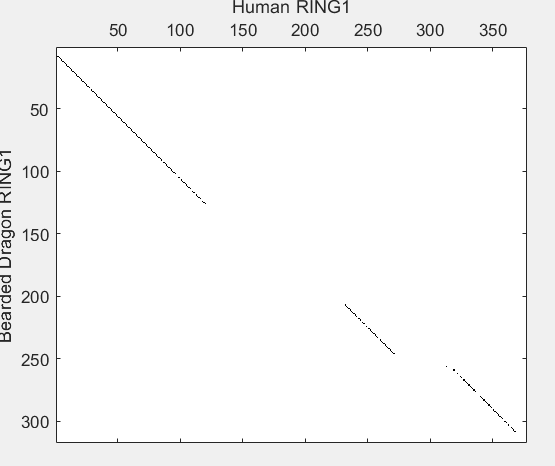

seqdotplot(human, bearded, 11,7);
title("Sequences alignment dotplot");
xlabel("Human RING1"); ylabel("Bearded Dragon RING1");

                a.Based on this plot, should you perform local or global alignment with these sequences? Why?

                - Should perform global alignment because we can see start and end are kind of aligned, with a little bit of the middle part, but there is a huge gap so a local alignment might even score better, try global with semilocal option?

        3. Global alignment can be performed using **nwalign **and local alignment using **swalign**. Use the type of alignment determined in question 2. Use the option **showalignment **to display the results**.** 

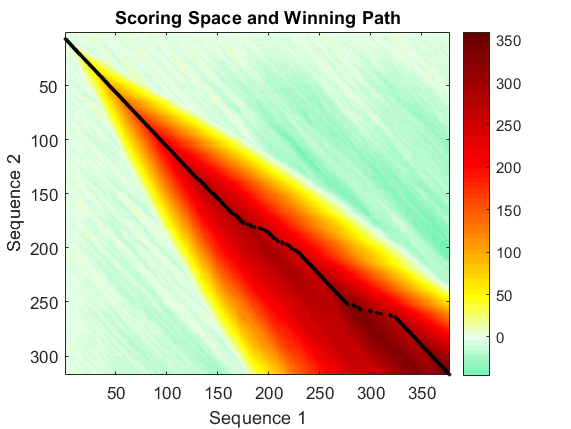

score1 = 359.6667

alignment1 = 3×383 char array
    '------MDGTEIAVSPRSLHSELMCPICLDMLKNTMTTKECLHRFCSDCIVTALRSGNKECPTCRKKLVSKRSLRPDPNFDALISKIYPSREEYEAHQDRVLIRLSRLHNQQALSSSIEEGLRMQAMHRAQRVRRPIPGSDQTTTMSGGEGEPGEGEGDGEDVSSDSAPDSAPGPAPKRPRGGGAGGSSVGTGGGGTGGVGGGAGSEDSGDRGGTLGGGTLGPPSPPGAPSPPEPGGEIELVFRPHPLLVEKGEYCQTRYVKTTGNATVDHLSKYLALRIALERRQQQEAGEPGGPGGGASDTGGPDGCGGEGGGAGGGDGPEEPALPSLEGVSEKQYTIYIAPGGGAFTTLNGSLTLELVNEKFWKVSRPLELCYAPTKDPK'
    '      |||||||||||||||||||||||||||:|||||||||||||||||||||||||||||||||||||||||||||||||||||||||:|||||||||| :|:|||||||| ||:||||:||||:|:||||:  |  :::||:||:| :  ::::   ::|: | |: | ||: || |   |  |:       :         | | : ||    |:   |  |||   |  ::||||||||||:||:|| | ||||||||:||||||||||||||||||     ||  | ||        ||     |   |        ||   || ||||||||||: :||||||||||:||||||||:||:|:|||| |||||: |'
    'PCQEAMMDGTEIAVSPRSLHSELMCPICLDMLKHTMTTKECLHRFCSDCIVTALRSGNKECPTCRKKLVSKRSLRPDPNFDALISKIYPSRDEYEAHQDRVLAKLNRLHNQQALRSSMEEGLKMQAMNRGQRVRKH-PQESDNTTFSGAE-DNCDSRSHLSNASAPSQPE-A-GPSRKRSR---A

[score1, alignment1] = nwalign(human, bearded, 'showscore',true,'glocal', true)

        a) What do the results show?

            The evaluation of the score of best alignment

        b) If you set the parameter **SHOWSCORE **to be true, what does the given plot mean?

            The evaluation of the scoring matrix

        c) Find out what the scoring matrices and the gap penalties are by default.  What do these parameters mean and why they are important?    

            BLOSUM50, gap open = extend gap 8

          4. To assess the significance of the scores obtained for our alignment we need to compare the scores to that of random sequences which have the same properties as the real sequence.  We will do this two ways; 

        a) Firstly with **randperm**.  Use this function to permute the data for the one of the sequences many times and generate the alignment scores of these permuted sequences to the original for the other.  Plot these sequences into a histogram and show the real data on this plot as well.  Is it significant?

PERMUTATIONS = 1000;
scores1 = double.empty;

for x=1:PERMUTATIONS
    % generate permutation on bearded seq
    rand = randperm(bearded_length);
    perm = bearded(rand);
    % generate alignment score
    scores1(x) = nwalign(human, perm,'showscore',false);
end

b= ceil(PERMUTATIONS/5);
ph1 = evfit(scores1)

ph1 =   -75.2034   11.1253


x = min(scores1):max([scores1 score1]);
y = evpdf(x,ph1(1),ph1(2));

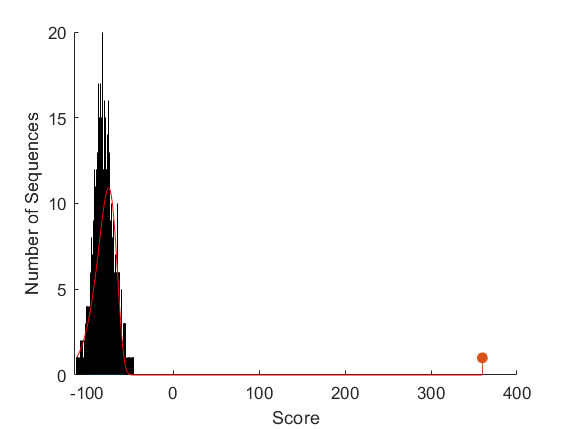

figure
hold on;
c = histogram(scores1, b);
stem(score1,1,'filled')
xlabel('Score'); ylabel('Number of Sequences');
scale = PERMUTATIONS* c.BinWidth;
plot(x,scale*y,'r');
hold off;

       b) Secondly, let’s generate random sequences with the same features as our original sequence. Use **aacount** to count the number of times each amino acid occurs in the shorter sequence.  Now use **randseq **with the **FROMSTRUCTURE** option to generate sequences based on that distribution.  Make another histogram, is the real data significant?

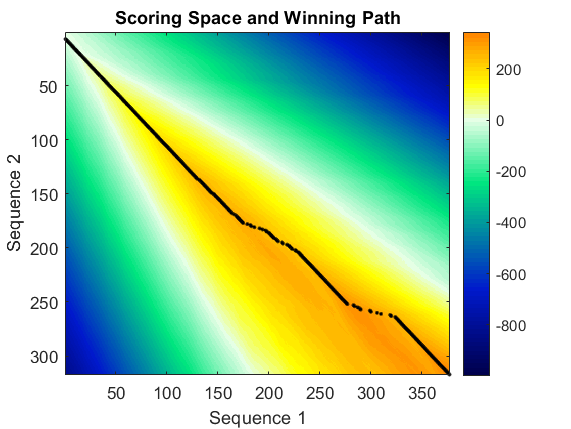

score2 = 343.6667

alignment2 = 3×383 char array
    '------MDGTEIAVSPRSLHSELMCPICLDMLKNTMTTKECLHRFCSDCIVTALRSGNKECPTCRKKLVSKRSLRPDPNFDALISKIYPSREEYEAHQDRVLIRLSRLHNQQALSSSIEEGLRMQAMHRAQRVRRPIPGSDQTTTMSGGEGEPGEGEGDGEDVSSDSAPDSAPGPAPKRPRGGGAGGSSVGTGGGGTGGVGGGAGSEDSGDRGGTLGGGTLGPPSPPGAPSPPEPGGEIELVFRPHPLLVEKGEYCQTRYVKTTGNATVDHLSKYLALRIALERRQQQEAGEPGGPGGGASDTGGPDGCGGEGGGAGGGDGPEEPALPSLEGVSEKQYTIYIAPGGGAFTTLNGSLTLELVNEKFWKVSRPLELCYAPTKDPK'
    '      |||||||||||||||||||||||||||:|||||||||||||||||||||||||||||||||||||||||||||||||||||||||:|||||||||| :|:|||||||| ||:||||:||||:|:||||:  |  :::||:||:| :  ::::   ::|: | |: | ||: || |   |  |:       :         | | : ||    |:   |  |||   |  ::||||||||||:||:|| | ||||||||:||||||||||||||||||     ||  | ||        ||     |   |        ||   || ||||||||||: :||||||||||:||||||||:||:|:|||| |||||: |'
    'PCQEAMMDGTEIAVSPRSLHSELMCPICLDMLKHTMTTKECLHRFCSDCIVTALRSGNKECPTCRKKLVSKRSLRPDPNFDALISKIYPSRDEYEAHQDRVLAKLNRLHNQQALRSSMEEGLKMQAMNRGQRVRKH-PQESDNTTFSGAE-DNCDSRSHLSNASAPSQPE-A-GPSRKRSR---A

[score2, alignment2] = nwalign(human, bearded,'showscore',true)

scores2 = double.empty;
aa_bearded = aacount(bearded);

for x=1:PERMUTATIONS
    % generate permutation on bearded seq
    rand_seq_bearded = randseq(bearded_length, 'fromstructure',aa_bearded);

    % generate alignment score
    scores2(x) = nwalign(human, rand_seq_bearded,'showscore',false);
end

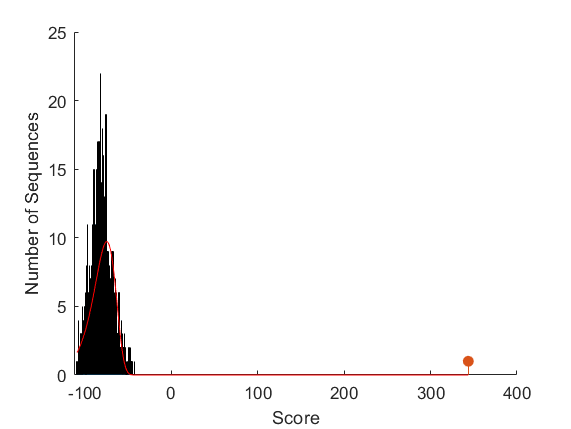

ph2 = evfit(scores2);
x = min(scores2):max([scores2 score2]);
y = evpdf(x,ph2(1),ph2(2));

figure
hold on;
c =  histogram(scores2,b);
stem(score2,1,'filled')
scale = PERMUTATIONS*c.BinWidth;
plot(x,scale*y,'r');
xlabel('Score'); ylabel('Number of Sequences');
hold off;

## Assignment: 

Another friend of Peter’s studies unicellular microalgae (symbiodinium necroappetens) which also have a RING1 protein, but it is much longer than the human version.  The accession number of this protein is CAE7901930. How close is the algae version to the human protein?  Explain your results.

Make a new livescript with your working and explanations for this part and submit this file to the assignment on canvas. 